# **Computer Vision**

# **Lab 3. Image Segmentation**

**  Departamento de Electrónica. Universidad de Alcalá.**

**Students: Filip Ćelepirović, Helena Potočki**

**Date: 11.11.2023.**

The main objective of this practice is to become familiar with image segmentation techniques:

- From simple levels that require intervention by the user (supervised segmentation) to set thresholds, establish model parameters, etc., to more complex levels that work automatically or semi-automatically (unsupervised segmentation).

- From techniques based on the histogram, clustering techniques (in regions) and edge techniques. 

- Based on linear and non-linear classification methods of each pixel of the image in the corresponding region.

 Throughout the practice you will be asked to: 

- Apply some of the studied segmentation techniques in a practical way, verifying their problems and limitations.

- Compare some segmentation techniques with others, analyzing their percentage of success.

- Distinguish supervised vs unsupervised segmentation.

- Differentiate segmentation based on linear versus non-linear techniques.

 As in the previous practice, once the proposed activities have been completed, a report will be delivered, made on this same file, that it includes for each exercise:  

- Original image/Processed image/requested data.

- Intermediate images (if they exist and are of interest).

- Code.

- Explanation of the code and justification/conclusions on the result obtained.

It will be valued positively: the expansion of the memory with the explanations that you consider appropriate, additional tests (modifying parameters, using other images that highlight some effect of the processing, etc.), description of problems that arose in the execution of the practice and solution provided, etc. Perform each exercise as an independent section, viewing the results together with a subplot when appropriate, and inserting instructions to close windows (close all), remove variables from the workspace (clear all), and pause (pause), where necessary. 

The delivery will be made in the Virtual Classroom of the subject: Contents --> Labs --> Lab 3. Report

**Suggested exercises:**

** 1. Linear Supervised Histogram-based Segmentation:**

- Open the image "pimientos.jpg".

- Convert it to grayscale image.

- Get and display grayscale image histogram.

- In view of the histogram, use as many thresholds as necessary and the appropriate values to segment each of the objects in the image. You can enter them with a slider (*numeric slider*) or by requesting them at the Matlab prompt with the instruction: threshold = input('Enter threshold value X in view of the histogram figure '). 

- Display the segmentation (either with objects of different colors in the same image, or using a different image for each object).

- Is it easy to segment the different objects? Justify your answer.

- Try to improve the result based on the color image and/or its different components.

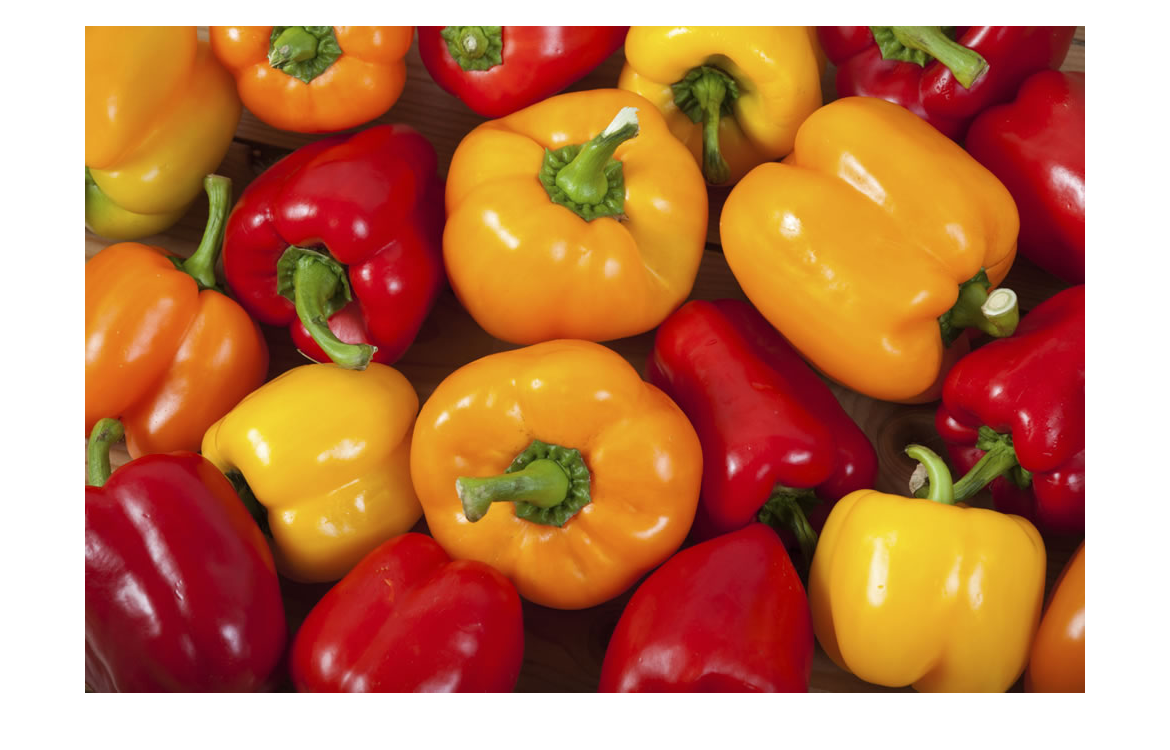

image = imread("pimientos.jpg");
grayImage = rgb2gray(image);
imshow(image);

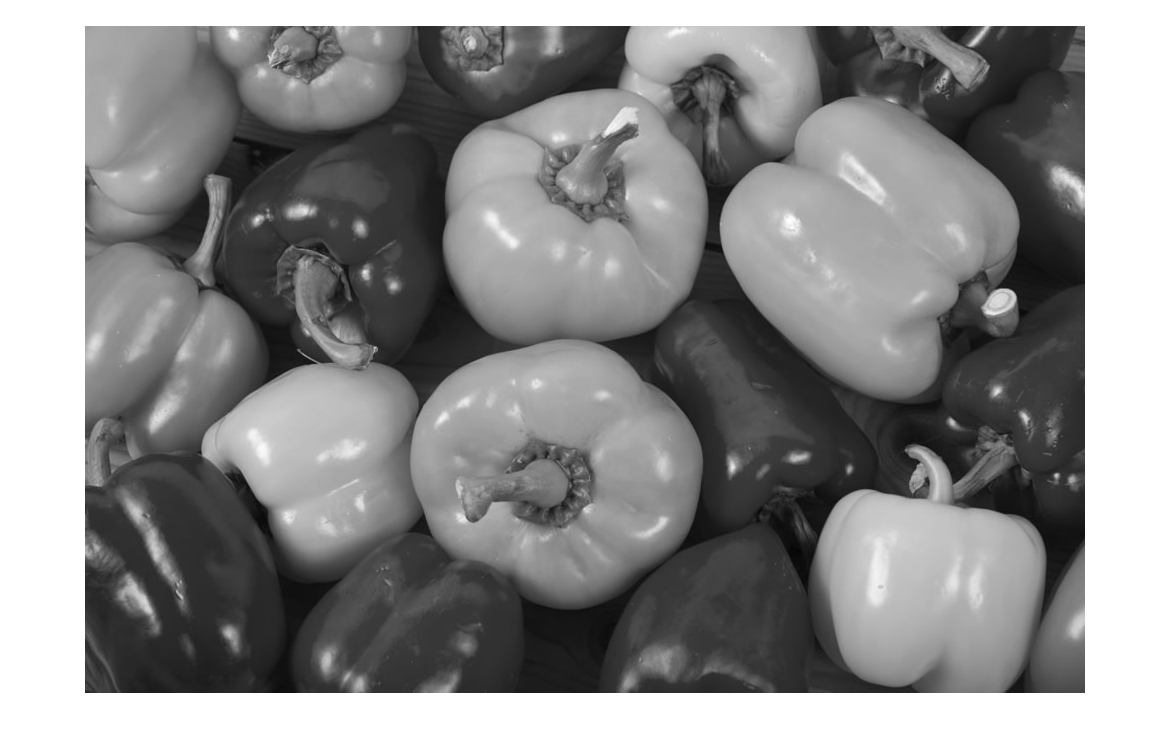

imshow(grayImage)

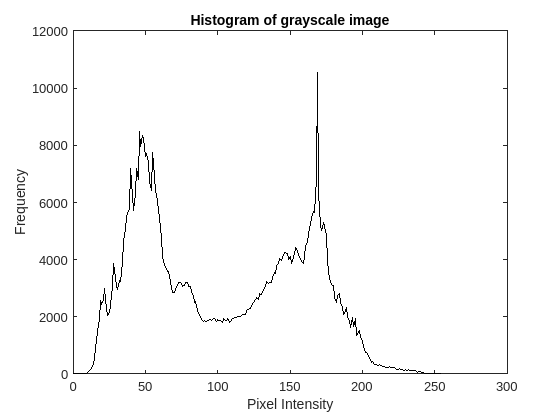

[counts, binLocations] = imhist(grayImage);
figure;
plot(binLocations, counts, 'k');
title('Histogram of grayscale image');
xlabel('Pixel Intensity');
ylabel('Frequency');

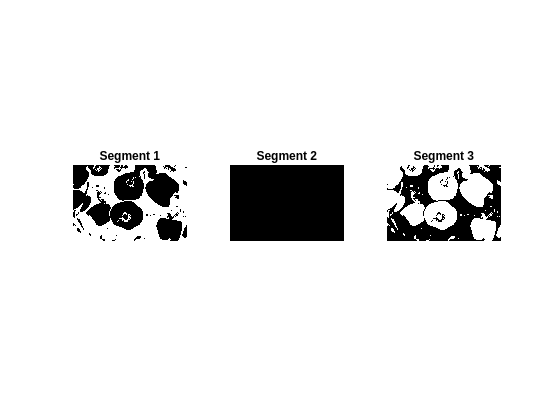

numThresholds = 2;
thresholds = zeros(1, numThresholds);
for i = 1:numThresholds 
threshold = 100;
thresholds(i) = threshold;
end
segmentedPaprikas = cell(1, numThresholds + 1);
segmentedPaprikas{1} = grayImage < thresholds(1);
for i = 2:numThresholds
    segmentedPaprikas{i} = (grayImage >= thresholds(i - 1)) & (grayImage < thresholds(i));
end
segmentedPaprikas{numThresholds + 1} = grayImage >= thresholds(numThresholds);
figure;
for i = 1:(numThresholds + 1)
    subplot(1, numThresholds + 1, i);
    imshow(segmentedPaprikas{i});
    title(['Segment ', num2str(i)]);
end

**2. Linear unsupervised segmentation:**

- **Threshold** the image "eight.tif" with the ***imbinarize*** function, using a global threshold previously calculated with Matlab's ***graythresh*** function (unsupervised method: it does not require the user's observation of the histogram, nor the choice of thresholds from it): 

                    *   The *graythresh* function uses the Otsu method to choose the global segmentation threshold, minimizing the variance within the elements of the classes and maximizing it between classes.

                    *  The *imbinarize* function thresholds grayscale images. If the original image is in color, it is necessary to previously transform it to grayscale with the corresponding function depending on its format (*rgb2gray*, etc...).  

                         level = graythresh(I);

                         BW = *imbinarize*(I,level);

                         figure, imshow(BW)

- Does unsupervised segmentation work correctly with image "eigth.tif"? Why?

- Try other Matlab images with histograms of different shapes. Does *graythresh* correctly segment the images in all cases? If not, with what type of images does it usually work best/worst?

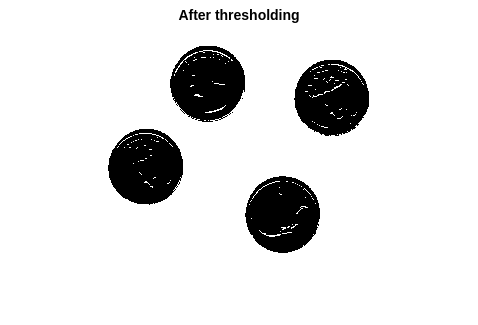

eight = imread("eight.tif");
level = graythresh(eight);
binarizedEight = imbinarize(eight, level);
figure;
imshow(binarizedEight);
title('After thresholding');



%{
this method of thresholding didn't do well on the given picture ('eight.tiff) because the picture didn't really have strongly accented borders on some parts/segments of the picture. 
this method would probably work better on images that don't have that much similar shades in some borders between segments or segment and background or those that are not important. 
although this were 4 coins that are well distinguished, the things inside coins were poorly shown. we have also tried the saturn picture and it was shown well but, again, only outer shape and rings. 
but the inside shades were lost because automatic thresholding set parameters in an order that is not compatible with anything else but firm borders and firm shade difference. 

%}

**3. Compare the two previous sections: supervised versus unsupervised linear segmentation, indicating advantages and disadvantages of each.**

%{ 
Supervised linear segmentation: 
Has good user control - we have control over the entire segmentation process and we can adapt it to our needs, although we still need to have some understanding of what we want to do and methods to do that, as well as very good understanding of image content
The disadvantage is actually the fact that user needs to understand image content and tools and also, if we have a lot of content to perform thresholding on, it takes a lot of time to do that because we need to do everything manually
Unsupervised linear segmentation: 
Fast and easy, we don't need to know much or even try to customize process of thresholding
It can be really good and precise on many types of content
Bad performance on complexed content, lack of precisement on complex content
Algorithms are not that smart as human eye, often it happens that they do not consider some details important as they actually are
All in all, it is always better to use supervised, but since it takes a lot of time and work, it is important to have the knowledge and understanding of situations when we can use unsupervised to help ourselves and when to use supervised to make it precise and correct.
%}

**4. Edge-based segmentation:**

- Open image "coins.png".

- Detect edges using the Canny filter. Use *numeric sliders* to configure the various parameters and visualize the effect of the different settings. Comment on the effects on the edges of changing each parameter.

- Close contours by dilating the obtained edges (*imdilate*). View results.

- Fill the obtained contours (*imfill*).

- Label the different objects with *bwlabel* and show the final result.

- Repeat steps 1 to 5 using the `'sobel'` mask and compare the results (canny - sobel).

- Repeat steps 1 to 5 and compare the results with or without dilation (step 3). Justify your answer.

- Compare the results obtained when using different structuring elements in the dilation. Justify your answer.

- Compare the results by performing a dilation (*imdilate*) versus a closure (*imclose*). Justify your answer.

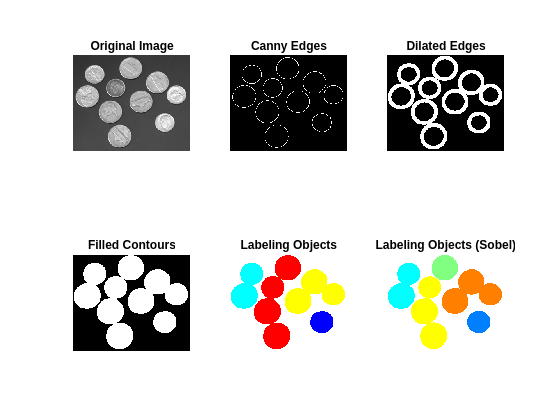

% Load the image
originalImage = imread('coins.png');

% Alternative method to convert the image to grayscale
grayImage = mean(originalImage, 3); % Computing the mean across the RGB channels

% Display the original image
figure;
subplot(2, 3, 1);
imshow(originalImage);
title('Original Image');

% Step 1: Detect edges using the Canny filter
threshold1 = 0.2;
threshold2 = 0.5;

edgeImageCanny = edge(grayImage, 'Canny', [threshold1, threshold2]);

% Display the Canny edges
subplot(2, 3, 2);
imshow(edgeImageCanny);
title('Canny Edges');

% Step 2: Dilate the obtained edges
seDilate = strel('disk', 5); % Adjust the size of the structuring element as needed
dilatedEdges = imdilate(edgeImageCanny, seDilate);

% Display the dilated edges
subplot(2, 3, 3);
imshow(dilatedEdges);
title('Dilated Edges');

% Step 3: Fill the obtained contours
filledImage = imfill(dilatedEdges, 'holes');

% Display the filled contours
subplot(2, 3, 4);
imshow(filledImage);
title('Filled Contours');

% Step 4: Label different objects
labeledImage = bwlabel(filledImage, 8);
subplot(2, 3, 5);
imshow(label2rgb(labeledImage, 'jet', 'w', 'shuffle'));

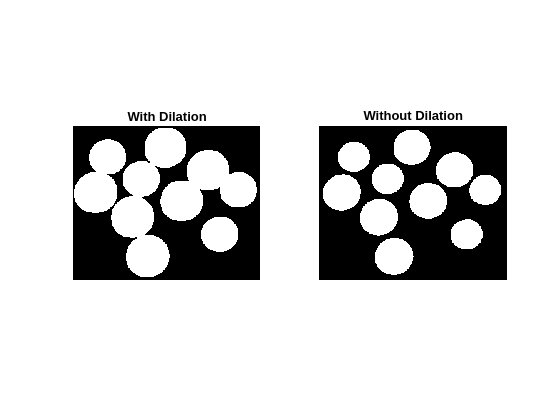

title('Labeling Objects');

% Repeat steps 1 to 5 using the 'sobel' mask
edgeImageSobel = edge(grayImage, 'Sobel');
dilatedEdgesSobel = imdilate(edgeImageSobel, seDilate);
filledImageSobel = imfill(dilatedEdgesSobel, 'holes');
labeledImageSobel = bwlabel(filledImageSobel, 8);

% Display results with Sobel edges
subplot(2, 3, 6);

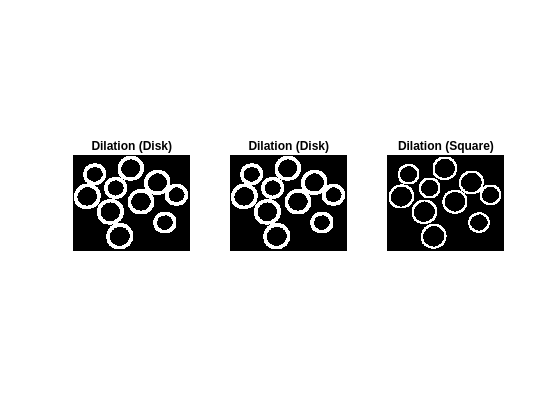

imshow(label2rgb(labeledImageSobel, 'jet', 'w', 'shuffle'));
title('Labeling Objects (Sobel)');

% Compare results with or without dilation
figure;
subplot(1, 2, 1);
imshow(filledImage);
title('With Dilation');

subplot(1, 2, 2);
imshow(imfill(edgeImageCanny, 'holes'));
title('Without Dilation');

% Compare results with different structuring elements in dilation
figure;
seDisk = strel('disk', 5);
seSquare = strel('square', 5);

dilatedEdgesDisk = imdilate(edgeImageCanny, seDisk);
dilatedEdgesSquare = imdilate(edgeImageCanny, seSquare);

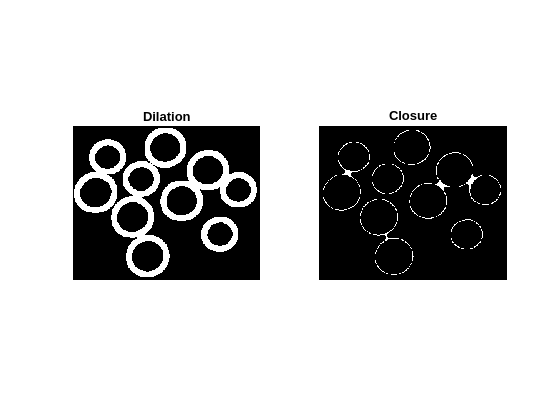


subplot(1, 3, 1);
imshow(dilatedEdges);
title('Dilation (Disk)');

subplot(1, 3, 2);
imshow(dilatedEdgesDisk);
title('Dilation (Disk)');

subplot(1, 3, 3);

imshow(dilatedEdgesSquare);
title('Dilation (Square)');

% Compare dilation versus closure
figure;
subplot(1, 2, 1);
imshow(imdilate(edgeImageCanny, seDilate));
title('Dilation');

subplot(1, 2, 2);
imshow(imclose(edgeImageCanny, seDilate));
title('Closure');


**5. Line detection using the Hough transform:**

- Using the Hough transform, draw the 7 longest lines in the image 'despacho1.jpg'. 

- Verify the effect of the 'FillGap' and 'MinLength' parameters by modifying their value (for example, using sliders) and viewing the result. Comment on its effect on the detected lines.

- Calculate the number of peaks (`length(P)`) and the number of lines (`length(lines)`) obtained. Are they the same or different? Why?

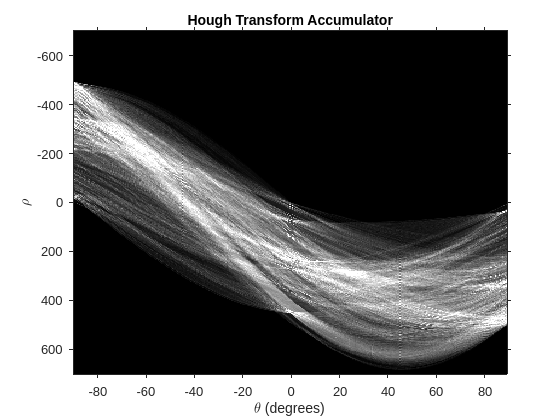

% Load the image
originalImage = imread('despacho1.jpg');

% Alternative method to convert the image to grayscale
grayImage = mean(originalImage, 3); % Computing the mean across the RGB channels

% Perform edge detection using the Canny method
edgeImage = edge(grayImage, 'Canny');

% Define the Hough transform parameters
thetaResolution = 0.5;
rhoResolution = 1;

% Perform the Hough transform
[H, theta, rho] = hough(edgeImage, 'Theta', -90:thetaResolution:89, 'RhoResolution', rhoResolution);

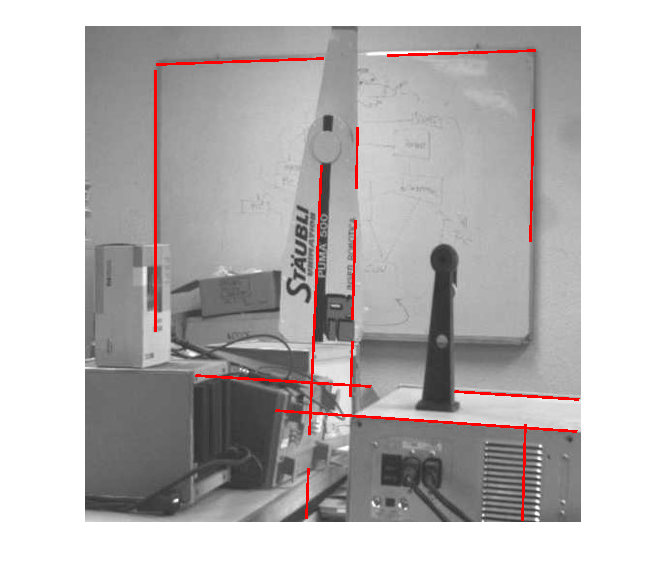


% Display the Hough transform accumulator
figure;
imshow(imadjust(mat2gray(H)), 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit');
title('Hough Transform Accumulator');
xlabel('\theta (degrees)');
ylabel('\rho');
axis on;
axis normal;
hold on;

% Set the 'FillGap' and 'MinLength' parameters
fillGap = 20;
minLength = 50;

% Manually find peaks in the Hough transform
P = houghpeaks(H, 7);
[row, col] = ind2sub(size(H), P);

% Overlay the detected lines on the original image

figure;
imshow(originalImage);
hold on;

Number of peaks (length(P)): 7


Number of lines (length(lines)): 13


% Extract and draw the 7 longest lines
lines = houghlines(edgeImage, theta, rho, P, 'FillGap', fillGap, 'MinLength', minLength);
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'r');
end

% Display the number of peaks and the number of lines
fprintf('Number of peaks (length(P)): %d\n', length(row));
fprintf('Number of lines (length(lines)): %d\n', length(lines));



**6. Circle detection using the Hough transform:**

- Using the Hough transform, locate and draw the contour of the cells in the '**blood1.tif**' image whose radius is between 7 and 20 pixels. If necessary, consider thresholding the image and/or inverting it before applying the transform.

- Highlight the largest cell using a different color.

- How many cells did you find?

% Load the image
image = imread('blood1.tif');

% Alternative method to convert the image to grayscale
grayImage = mean(image, 3); % Computing the mean across the RGB channels

% Invert the image if necessary (based on the characteristics of the image)
invertedImage = imcomplement(grayImage);


% Perform edge detection using Canny
edgeImage = edge(invertedImage, 'Canny');

% Define the radius range for circle detection
minRadius = 7;
maxRadius = 20;

% Use Hough transform to detect circles
[centers, radii, metric] = imfindcircles(edgeImage, [minRadius, maxRadius]);

% Find the index of the largest circle
[~, idx] = max(metric);

% Display the results
figure;
imshow(image);
hold on;

% Draw all detected circles

Number of cells detected: 19


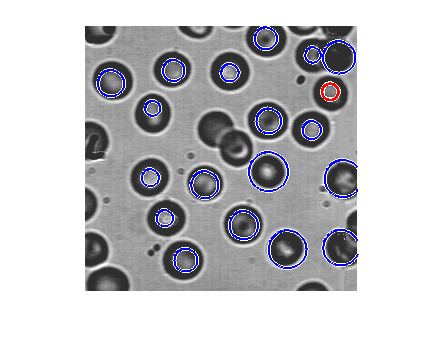

viscircles(centers, radii, 'EdgeColor', 'b');


% Highlight the largest circle in a different color (e.g., red)
highlightedCenter = centers(idx, :);
highlightedRadius = radii(idx);
viscircles(highlightedCenter, highlightedRadius, 'EdgeColor', 'r', 'LineWidth', 2);

% Count the number of detected cells
numCells = numel(radii);
fprintf('Number of cells detected: %d\n', numCells);

hold off;


**7. Watershed Transform:**

- Load the image '**circles.png**', threshold it and perform segmentation using the Watershed transform. Is there over-segmentation, that is, are there many more segmented objects  than there are in the original image? If so, try to reduce it (using, for example, morphological operators).

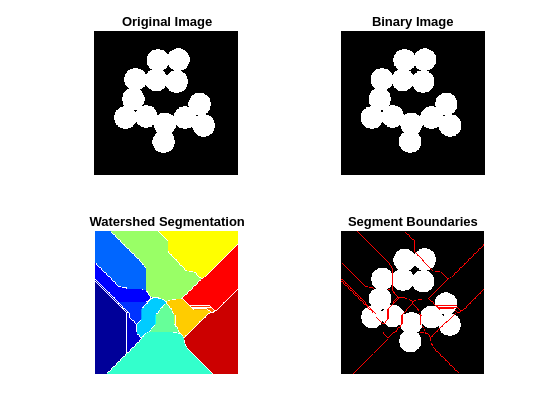

% Load the image
originalImage = imread('circles.png');

% Alternative method to convert the image to grayscale
grayImage = mean(originalImage, 3); % Computing the mean across the RGB channels

% Threshold the image
thresholdValue = graythresh(grayImage);
binaryImage = imbinarize(grayImage, thresholdValue);

% Perform morphological operations to reduce over-segmentation
se = strel('disk', 5); % Adjust the size of the structuring element as needed

% Closing operation to connect nearby regions
closedImage = imclose(binaryImage, se);

% Fill holes in the image
filledImage = imfill(closedImage, 'holes');

% Compute the distance transform of the filled image
D = -bwdist(~filledImage);

% Perform watershed segmentation

L = watershed(D);

% Display the results
figure;

Number of segmented objects: 18


subplot(2, 2, 1), imshow(originalImage), title('Original Image');
subplot(2, 2, 2), imshow(binaryImage), title('Binary Image');
subplot(2, 2, 3), imshow(label2rgb(L)), title('Watershed Segmentation');
subplot(2, 2, 4), imshow(imoverlay(originalImage, L == 0, [1 0 0])), title('Segment Boundaries');

% Assess the number of segmented objects
numSegments = max(L(:)) - 1; % Exclude the background
fprintf('Number of segmented objects: %d\n', numSegments);




**Optional**. Non-linear thresholding, for more that 2 classes. Consider that images of any size and type (indexed, color and in gray levels) can be read, which will always be converted to grayscale first.

**    8. **Implement a program that performs supervised segmentation by Gaussian models (nonlinear) for more than two classes. 

**    9. **Implement a program that performs unsupervised segmentation by Gaussian models (nonlinear) for more than two classes. 